# Computer Assignment 4 - Signals & Systems - Dr  Akhavan

### Question 0-1

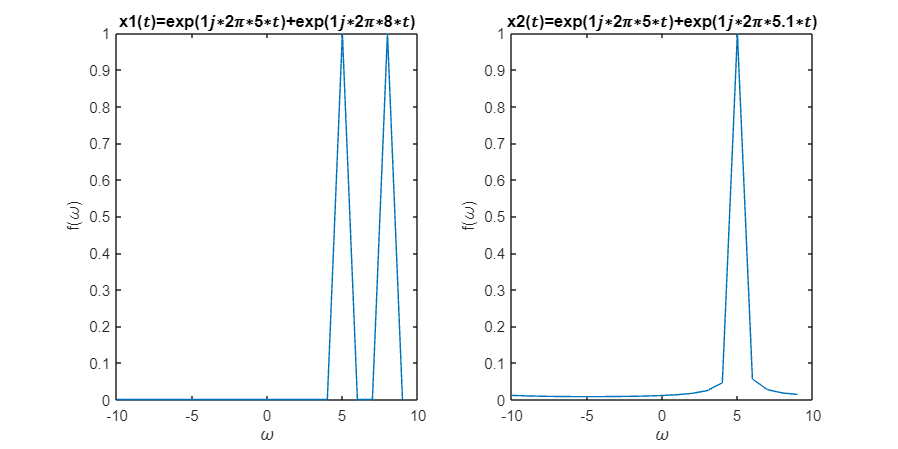

clc, clearvars, close all;
fs = 20;
t_start = 0;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x1 = exp(1j * 2 * pi * 5  * t) + exp(1j * 2 * pi * 8  * t);
x2 = exp(1j * 2 * pi * 5  * t) + exp(1j * 2 * pi * 5.1  * t);
figure('Position', [0,0,1000,500]);
y1 = fftshift(fft(x1));
y2 = fftshift(fft(x2));
subplot(1,2,1);
plot(f, abs(y1) / max(abs(y1)));
title("x1(𝑡)=exp(1𝑗∗2𝜋∗5∗𝑡)+exp(1𝑗∗2𝜋∗8∗𝑡)");
xlabel("\omega"); ylabel("f(\omega)")
subplot(1,2,2);
plot(f, abs(y2) / max(abs(y2)));
title("x2(𝑡)=exp(1𝑗∗2𝜋∗5∗𝑡)+exp(1𝑗∗2𝜋∗5.1∗𝑡)");
xlabel("\omega"); ylabel("f(\omega)")

### **Part 1**

clc, clearvars, close all;

#### **1 - 1)**

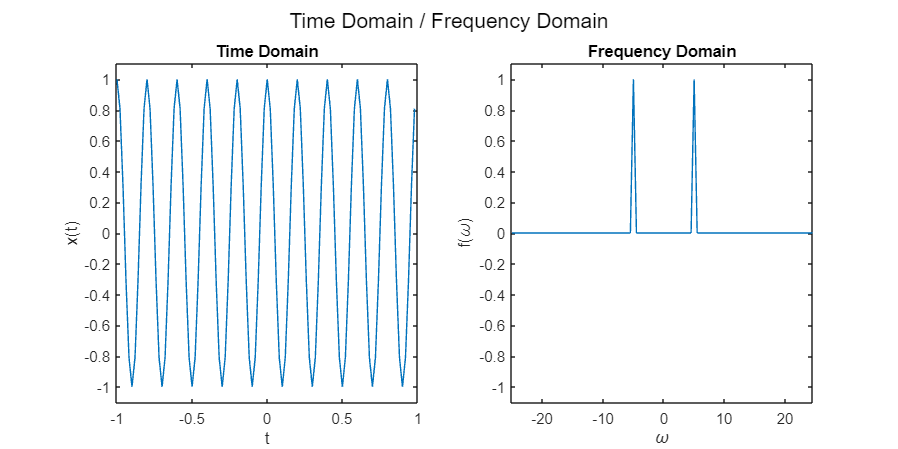

fs = 50;
t_start = -1;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x1 = cos(10 * pi * t);

figure('Position', [0,0,1000,500]);
sgtitle("Time Domain / Frequency Domain");
subplot(1,2,1)
plot(t, x1);
title ("Time Domain");
xlabel("t"); ylabel("x(t)");
ylim([-1.1,1.1])
y1 = fftshift(fft(x1));
y1 = y1 / max(abs(y1));

subplot(1,2,2)
plot(f, abs(y1));
ylim([-1.1,1.1])
title ("Frequency Domain");
xlabel("\omega"); ylabel("f(\omega)");

#### 1 - 2)

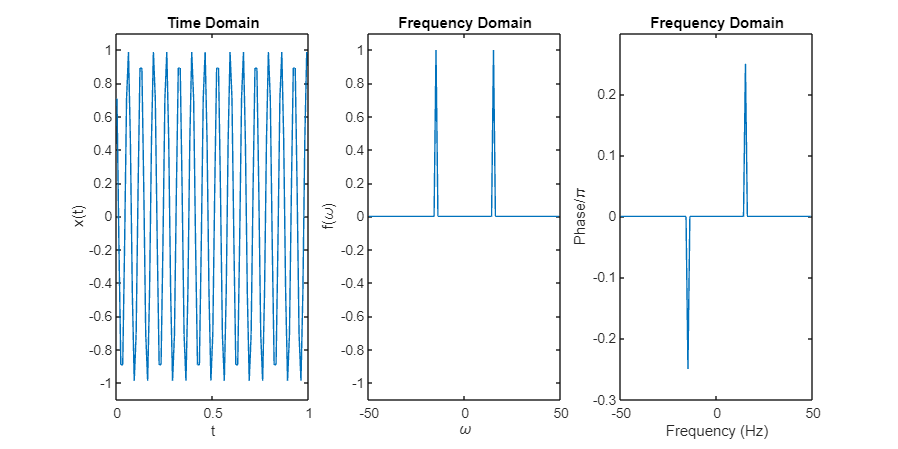

fs = 100;
t_start = 0;
t_end = 1;
ts = 1 / fs;
t = t_start:ts:t_end - ts;
T = t_end - t_start;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
x2 = cos(30 * pi * t + pi/4);
figure('Position', [0,0,1000,500]);
subplot(1,3,1)
plot(t, x2);
title ("Time Domain");
xlabel("t"); ylabel("x(t)");
ylim([-1.1,1.1])
y2 = fftshift(fft(x2));
y2 = y2 / max(abs(y2));
subplot(1,3,2)
plot(f, abs(y2));
title ("Frequency Domain");
xlabel("\omega"); ylabel("f(\omega)");
ylim([-1.1,1.1])
tol = 1e-6;
y2(abs(y2) < tol) = 0;
theta = angle(y2);
subplot(1,3,3)
plot(f, theta/pi);
title ("Frequency Domain");
xlabel("Frequency (Hz)"); ylabel("Phase/\pi");
ylim([-0.3,0.3])

### Part 2

clc, clearvars, close all;

#### 2 - 1) Creating mapset

Nch = 32; 
mapset = cell(2,Nch); 
Alphabet ='abcdefghijklmnopqrstuvwxyz .,!";'; 
for i = 1:Nch 
    mapset{1,i}=Alphabet(i); 
    mapset{2,i}=dec2bin(i-1,5); 
end

#### 2 - 2)

#### 2 - 3)

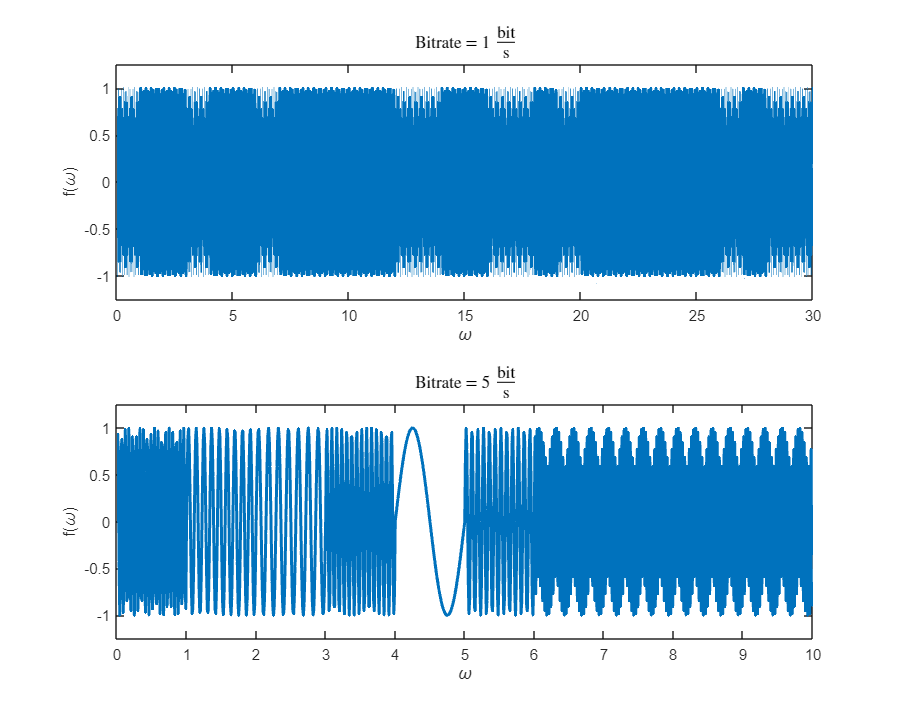

message = 'signal';
fs = 100;
ts = 1/fs;
bitrates = [1,5];
codedMessage = cell(1, 2);
figure('Position', [0,0,1000,800]);
for i = 1:2
    codedMessage{i} = coding_freq(message, bitrates(i), mapset);
    t = 0:(1/fs):(length(codedMessage{i})/fs)-(1/fs);
    subplot(2, 1, i);
    plot(t,codedMessage{i}, 'LineWidth', 2)
    title("Bitrate = " + bitrates(i) + " $\frac{\mathrm{bit}}{\mathrm{s}}$",'Interpreter','latex')
    xlabel("\omega"); ylabel("f(\omega)");
    ylim([-1.25, 1.25]);
end

### Functions

function binarizedMessage = message2binary(message, mapset)
    binarizedMessage = '';
    for charInMessage = message
        found = false;
        for charInMapSet = mapset
            if charInMessage == charInMapSet{1};
                binarizedMessage = [binarizedMessage, charInMapSet{2}];
                found = true;
                break;
            end
        end
        if ~found
            fprintf('Character "%c" not found in mapset. Skipping...\n', charInMessage);
        end
    end
end

function codedMessage = coding_freq(message ,bitrate, mapset)
while(mod(length(message), bitrate) ~= 0)
    message = [message, ';'];
end
fs = 100;
ts = 1/fs;
t_start = 0; t_end = 1;
t = t_start:ts:t_end - ts;

fStep = floor((fs / 2) / 2 ^ bitrate);
fStart = ceil(fStep / 2);
codedMessage = [];
binarizedMessage = message2binary(message, mapset);
for i = 1:bitrate:length(binarizedMessage)
    bit = binarizedMessage(i: i+bitrate-1);
    f = fStart + fStep * bin2dec(bit); 
    signal = sin(2*pi*f*t);
    codedMessage = [codedMessage, signal];
end
end